clc;clear;
n = 8;  % Cantidad de puntas de la estrella
r1= 1;  % radio exterior del círculo
r2= .5;  % radio interior del círculo


# 1) Construir un programa para que el PC adivine un número que piense el usuario. Una vez que el PC genera un número, el usuario debe responder con 1,2 o 3 para indicar si es mayor, menor o correcto.  El programa debe detectar si el usuario hace trampa (respuestas no concordantes con las anteriores)

# 2) Construir una estrella de n puntas alrededor de dos círculos con radios r1 y r2.

# 3) Generar n cantidad de tramos de recta a partir de parejas de puntos creados aleatoriamente en los rangos x[-mx,mx],y [-mx,mx] del plano cartesiano. Marcar los putos de cruce entre estas rectas (Octubre 25)

% 
dg = 360/n;
% g = 0:dg:360
g = linspace(0,360,n+1)

g =      0    45    90   135   180   225   270   315   360


g = g*pi/180;
[x,y]=pol2cart(g,r1)

x =     1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000


y =          0    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000



g2 = linspace(dg/2,360 + dg/2,n+1);
g2 = g2*pi/180;
[x,y]=pol2cart(g,r1)

x =     1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000


y =          0    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000


[x2,y2]=pol2cart(g2,r2)

x2 =     0.4619    0.1913   -0.1913   -0.4619   -0.4619   -0.1913    0.1913    0.4619    0.4619


y2 =     0.1913    0.4619    0.4619    0.1913   -0.1913   -0.4619   -0.4619   -0.1913    0.1913


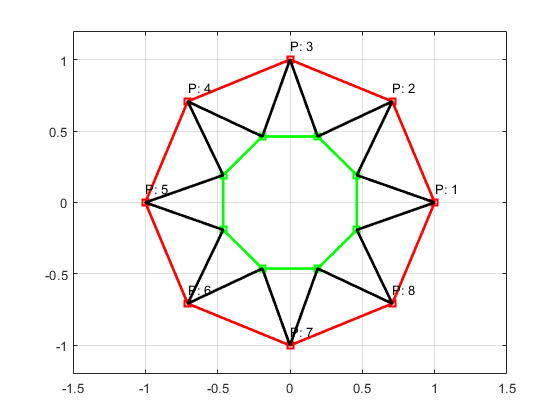

plot(x,y,'rsq-','linewidth',2);grid; axis([-1.5,1.5,-1.2,1.2]);
hold on
plot(x2,y2,'gsq-','linewidth',2);
xt = [];  yt = [];  % crear arreglos vacíos
for i = 1:n
    texto = ['P: ',num2str(i)];
    text(x(i),y(i)+.1,texto);
    xt = [xt x(i)]; xt = [xt x2(i)]; % adicionar elementos al arreglo - concatenar
    yt = [yt y(i)]; yt = [yt y2(i)];
end
xt = [xt x(1)];  % adicionar último elemento (igual al primero x)
yt = [yt y(1)];  % adicionar último elemento (igual al primero y)
plot(xt,yt,'k','linewidth',2);
hold off


X1 = [10,20,30,40]

X1 =     10    20    30    40


X2 = [15,25,35,45]

X2 =     15    25    35    45


Xt = zeros(1,8);
Xt(1:2:end)=X1

Xt =     10     0    20     0    30     0    40     0


Xt(2:2:end)=X2

Xt =     10    15    20    25    30    35    40    45
